clc
clear all
close all

syms a1 a2 a3 q1 q2 q_dot_1 q_dot_2 q_dot_dot_1 q_dot_dot_2 real
q=[q1 q2]';
q_dot=[q_dot_1 q_dot_2]';
q_dot_dot=[q_dot_dot_1 q_dot_dot_2]';

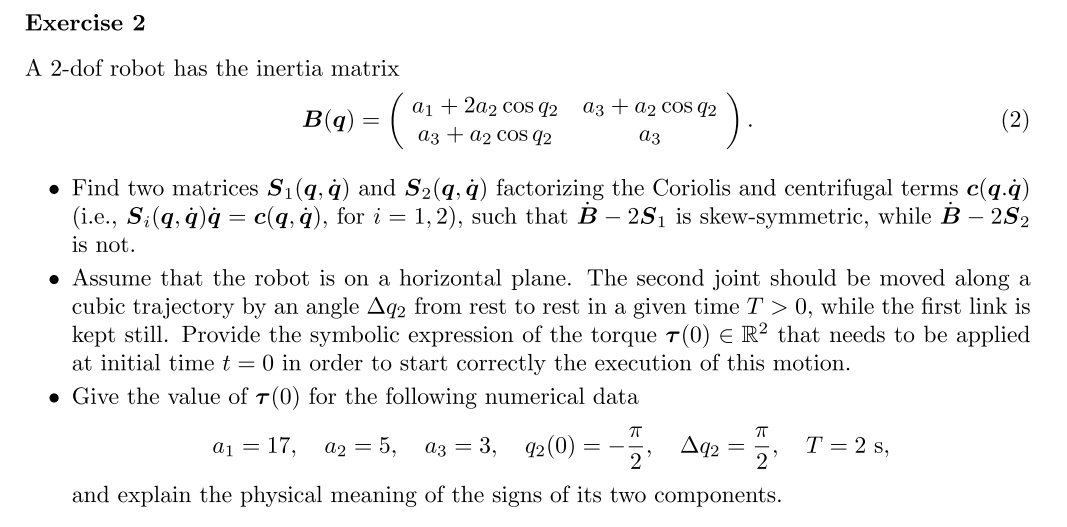

M=[a1+2*a2*cos(q2)  a3+a2*cos(q2);
   a3+a2*cos(q2)    a3];

S=[];
c_i=[]*q(1);
for i=1:length(q_dot)
    M_i=M(:,i);
    Ci=simplify(1/2*(jacobian(M_i, q)+jacobian(M_i, q)'-diff(M, q(i)) ));
    Si=q_dot'*Ci;
    S=[S; Si];
    c_i=[c_i; q_dot'*Ci*q_dot]; 
end

S

$$S = \left(\begin{array}{cc} -a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)-a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$


S_2=S+[-q2 q1; 0 0]

$$S\_2 = \left(\begin{array}{cc} -q_{2}-a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & q_{1}-a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)-a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$



diff(M, q1)*q_dot_1+diff(M, q2)*q_dot_2-2*S

$$ans = \left(\begin{array}{cc} 0 & 2\,a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)+a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ -2\,a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)-a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

diff(M, q1)*q_dot_1+diff(M, q2)*q_dot_2-2*S_2

$$ans = \left(\begin{array}{cc} 2\,q_{2} & 2\,a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)-2\,q_{1}+a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\\ -2\,a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right)-a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

syms tau T t Delta_q q_in real


traj = @(t) q_in+Delta_q*(-2*(t/T)^3 +3*(t/T)^2); 
traj_dot = diff(traj, t);
traj_dot_dot = diff(traj_dot, t)

$$traj\_dot\_dot = -\Delta_{q}\,\left(\frac{12\,t}{T^{3}}-\frac{6}{T^{2}}\right)$$


tau_d=M*q_dot_dot+c_i;

tau_t=subs(tau_d, {q_dot_1, q_dot_dot_1, q_dot_2, q_dot_dot_2},{0, 0, traj_dot, traj_dot_dot});
tau_zero=subs(tau_t, {t}, {0})

$$tau\_zero = \left(\begin{array}{c} \frac{6\,\Delta_{q}\,\left(a_{3}+a_{2}\,\cos\left(q_{2}\right)\right)}{T^{2}}\\ \frac{6\,\Delta_{q}\,a_{3}}{T^{2}} \end{array}\right)$$


simplify(subs(tau_zero, {a1, a2, a3, q2, Delta_q, T},{17, 5, 3, -pi/2, pi/2, 2}))

$$ans = \left(\begin{array}{c} \frac{9\,\pi }{4}\\ \frac{9\,\pi }{4} \end{array}\right)$$

var = vpa(ans)

$$var = \left(\begin{array}{c} 7.0685834705770347865409476123789\\ 7.0685834705770347865409476123789 \end{array}\right)$$